# MATLAB Real-time Audio Toolbox Session

# Audio  Toolbox 

- **audio plugins** as defined outside the MATLAB environment, see What Are DAWs, Audio Plugins, and MIDI Controllers?

- **object-oriented programming** (OOP) in the MATLAB® environment, to optimize your use of the audio plugin paradigm.

This the plugin structure in JUCE

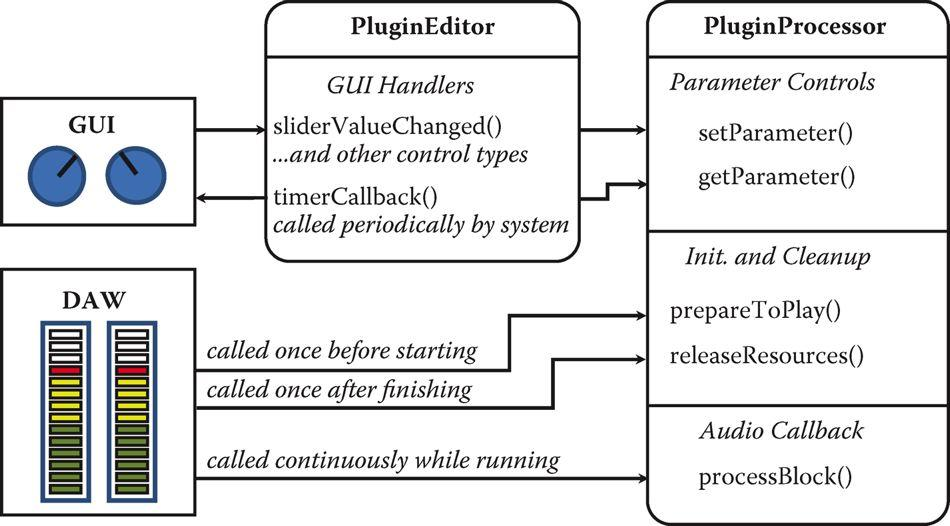

This is in MATLAB

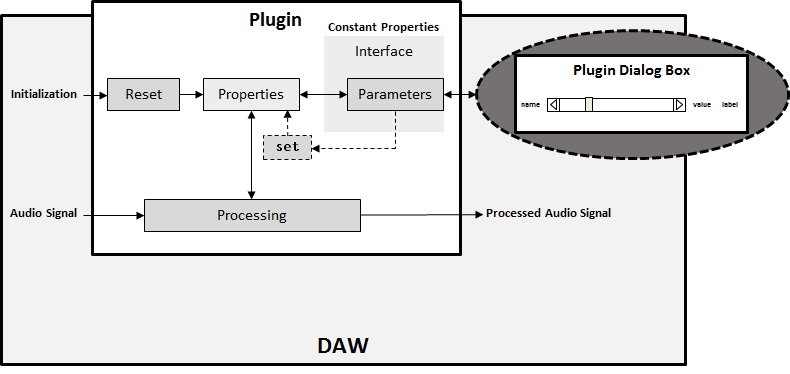

web(fullfile(docroot, 'matlab/object-oriented-programming.html?s_tid=CRUX_lftnav'))

## Classes in MATLAB

The basic purpose of a class is to define an object that **encapsulates data** and the operations performed on that data. 

For example, BasicClass defines a **property** and two **methods** that operate on the data in that property:

web(fullfile(docroot, 'matlab/matlab_oop/create-a-simple-class.html'))

**NOTE: **Live editor can handle Live Functions but not the classes. Please save your class to test and call from the Live Editor. 

#### Exercise: Write a NumericFractionalDelay class

- Property: a double number

- Method I: integerDelay(a) returns the integer part of the NumericFractionalDelay object

- Method II: fractionalDelay(a) returns the fractional part of the NumericFractionalDelay object

- Call each method

- Add a constructor

- TODO  inheritance.

### Audio Plugin Class

An audio plugin encapsulates an audio processing algorithm and enables you to tune the parameters of the algorithm while streaming audio.

The essential steps of the design are as follows:

- Define an Audio Plugin

- Prototype the Audio Plugin with [AudioTestBench](https://se.mathworks.com/help/audio/ref/audiotestbench-app.html)

- Validate and Generate a VST Plugin

Let's try the design first with a complete example: 

web(fullfile(docroot, 'audio/gs/design-an-audio-plugin.html'))

## Audio Plugins in MATLAB

In this example, you create a simple plugin, and then gradually increase complexity. Your final plugin uses a circular buffer to add an echo effect to an input audio signal

web(fullfile(docroot, 'audio/gs/audio-plugins-in-matlab.html'))

(If something goes wrong in editing, the final file myEchoPlugin.m is provided in this repository)

### Test Real-Time Audio in MATLAB

The easiest way of testing an audio plugin is by using [audioTestBench](https://se.mathworks.com/help/releases/R2019a/audio/ref/audiotestbench-app.html) (see also a [Walkthrough](https://se.mathworks.com/help/releases/R2019a/audio/ug/audio-test-bench-walkthrough.html))

audioTestBench myEchoPlugin;

A better practice is create the object first and run the audioTestBench with an instance of this object

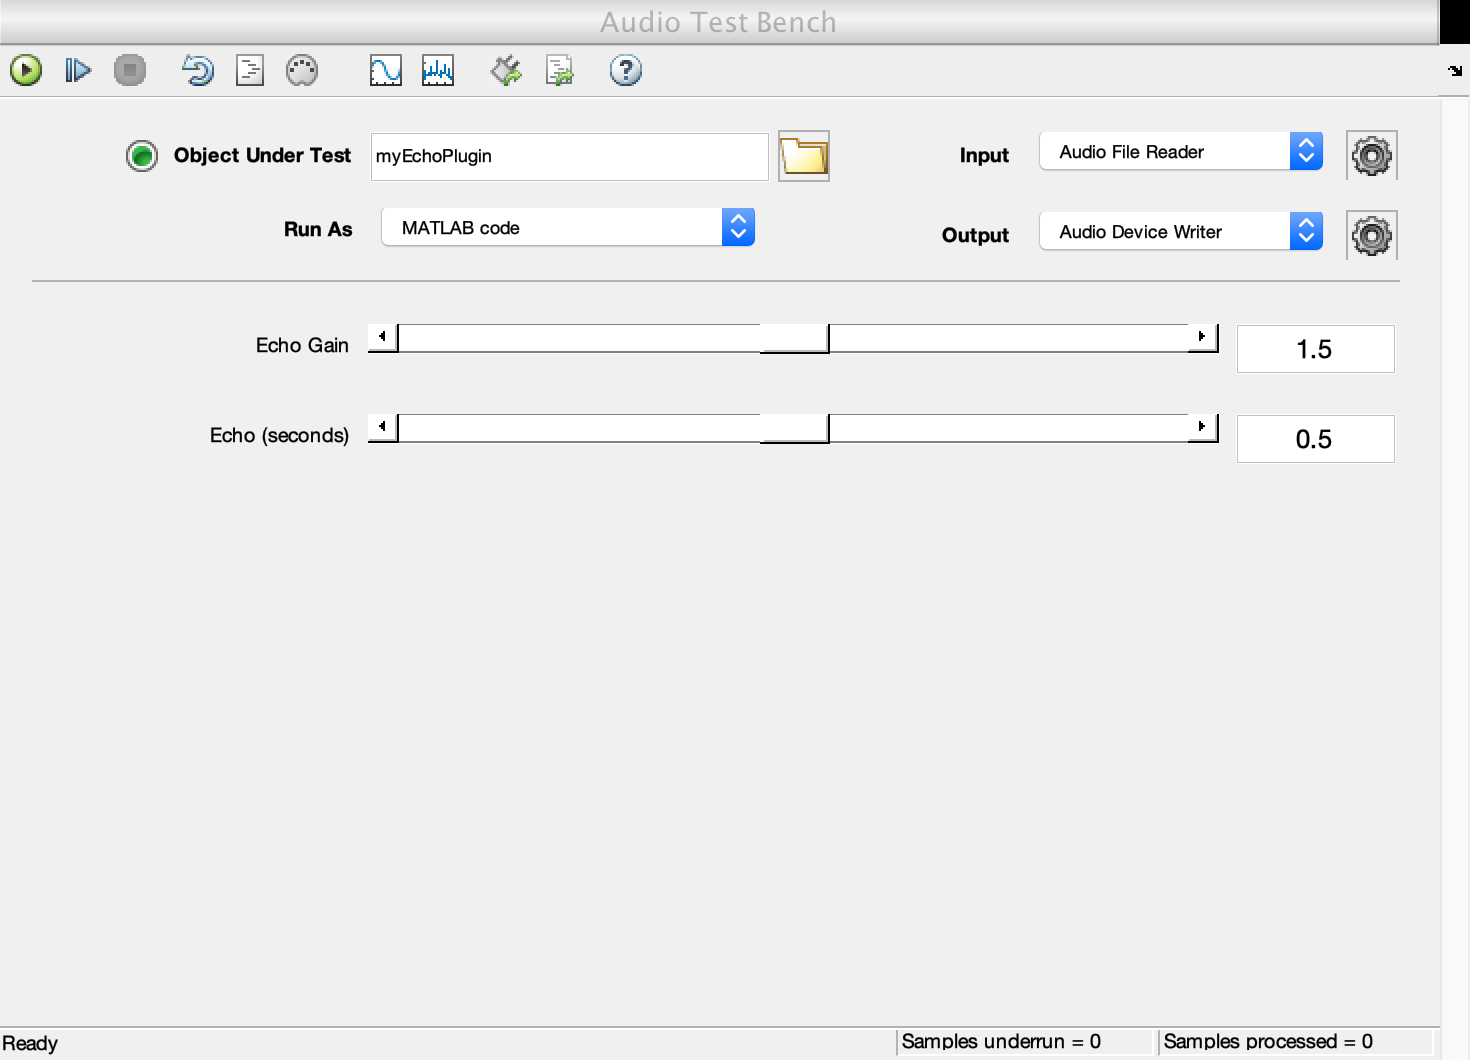

clear % The next line catches possible instantiation errors 

myE = myEchoPlugin 
audioTestBench myE;

Note: If the audioTestBench is too heavy on your system, you can run it once and create a test script.

% The following is a Test bench script for 'myEchoPlugin'.
% Generated by Audio Test Bench on 30-Mar-2019 09:00:24 +0100.

myE =   myEchoPlugin with properties:

               Gain: 1.5000
              Delay: 0.5000
    PluginInterface: [1x1 audioPluginInterface]


% See myEchoTestBenchScript for more info, we use it below.

After this, you can run your real-time script from the command line:

Of course, this test script can also be manually created, see 

web(fullfile(docroot, 'audio/gs/real-time-audio-in-matlab.html'))

### Optimize Latency in Your System

If you are hearing glitches, drop-outs, or your system feels very loaded even after scripting, please try out these:

web(fullfile(docroot, 'audio/gs/audio-io-buffering-latency-and-throughput.html?container=jshelpbrowser'))

Especially Windows users may want to consider ASIO drivers. If you have a sound device that comes with ASIO 

asiosettings

else install universal drivers from [http://www.asio4all.org/](http://www.asio4all.org/) 

# Basic Plugins: Panners

The audioPlugin `class` is shown on the right, and it consists from `properties` and `methods`.

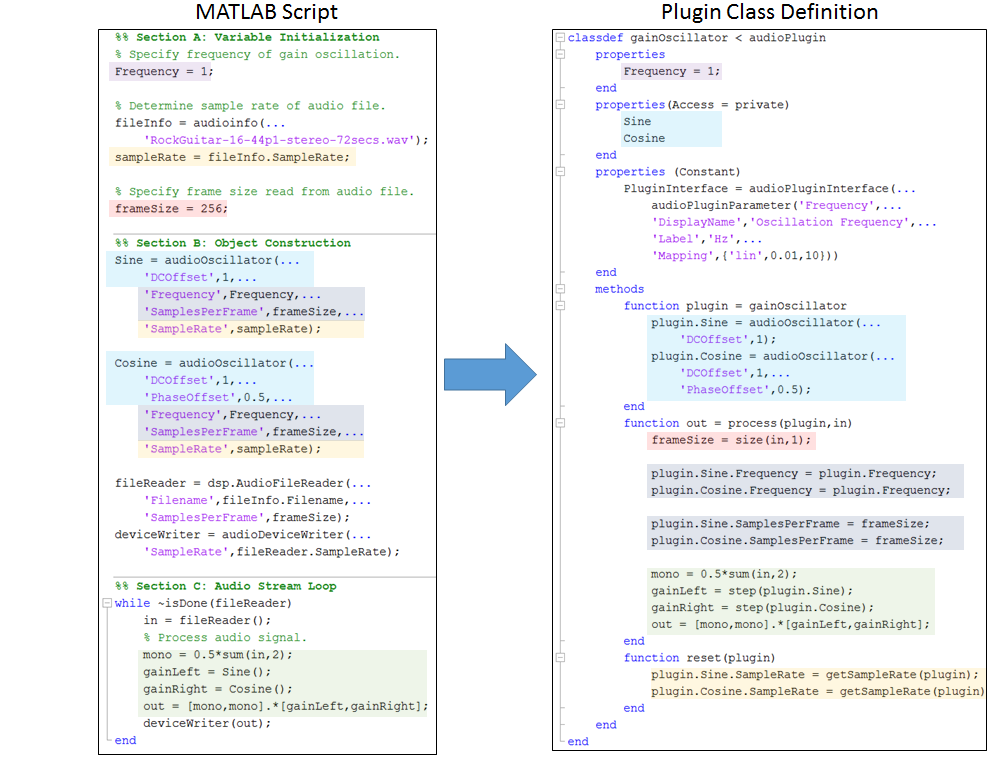

## Audio Pass-Thru

Our first example has only a `process(~,in) `for passing through the incoming audio buffer.

edit myWire.m;
p = myWire;
audioTestBench p;

There is not much to test in this plugin, but we can check the functionality of the scopes.

## First Parameter: Stereo Width

Now we will contol the source width with a slider in real time. 

For this, we create a new class `myWidth `and define the slider (as a `Constant PluginInterface`) property. 

Save this snippet at myWidth.m and test it on audioTestBench: the slider should act like a gain control.

Now change the process method of myWidth.m as follows

Reload the myWidth in audioTestBench and test if the slider is working as width expander.

### Exercise: myPanner

Can you convert myWidth to a linear panner plugin? Enter your new code here:

        % HINT: edit myFilePan.m<

# Basic Plugins: Filters

## FIR 1st order

p = myFIR1
audioTestBench p;

#### Exercise: Make a unity gain filter 

## IIR 1st order

edit myIIR1

## General Filter (2nd order or higher)

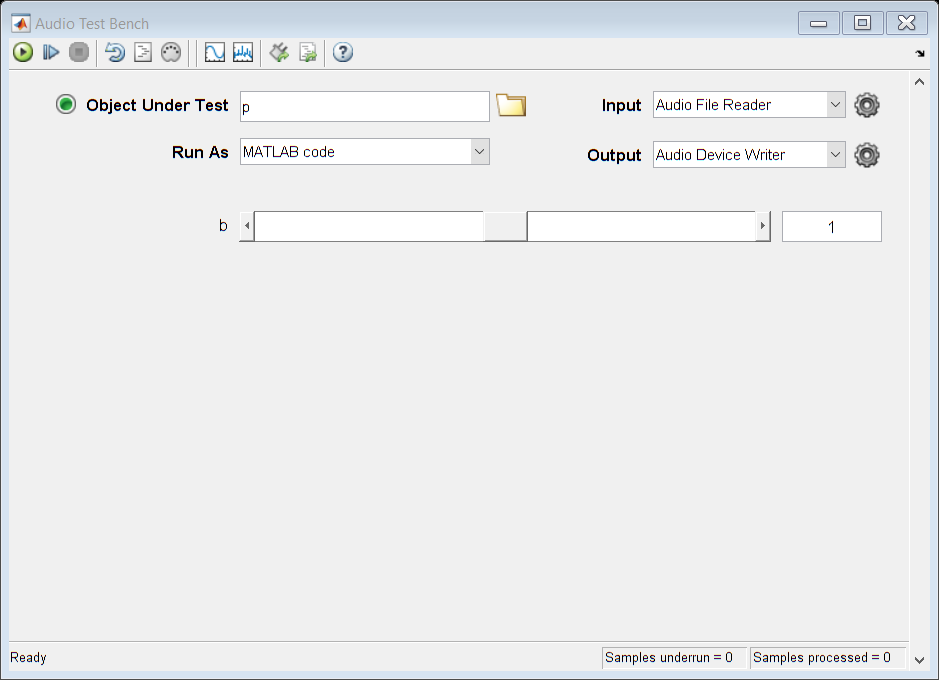

edit myFilter

# Sources and Sinks

Will be explained on the Audio Test Bench, see also below

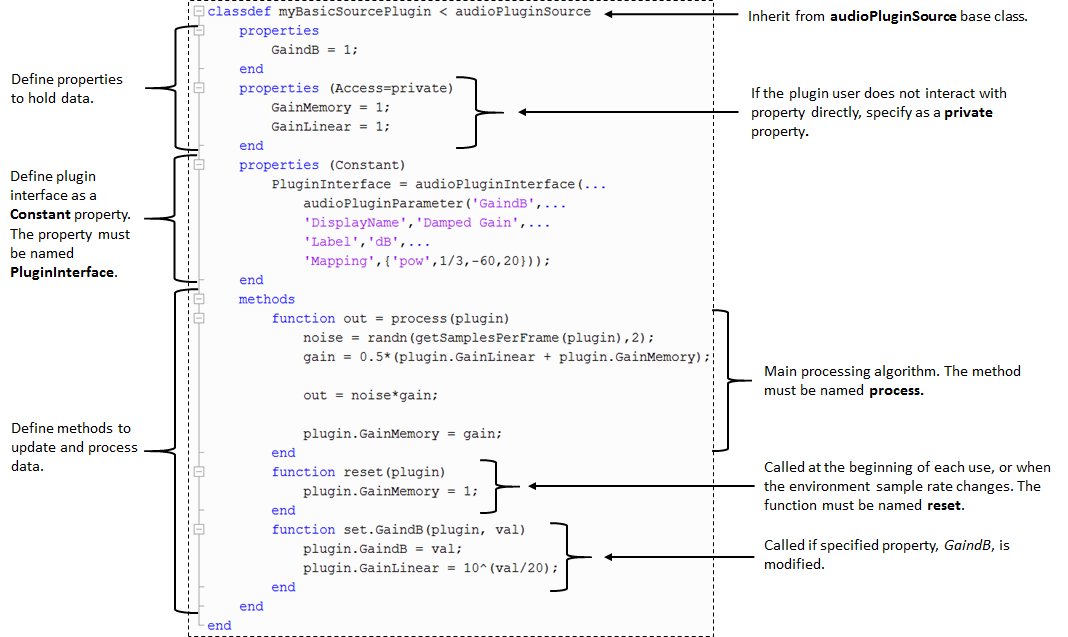

# Where to go from here

- [https://se.mathworks.com/help/audio/ug/audio-plugin-example-gallery.html](https://se.mathworks.com/help/audio/ug/audio-plugin-example-gallery.html) (Essential for Design Patterns)

- [https://github.com/cerkut/wpAudioPlugin](https://github.com/cerkut/wpAudioPlugin) 

- [https://www.hackaudio.com/](https://www.hackaudio.com/)

- MATLAB: [Creating VST Plugins with MATLAB Video - with Code](https://se.mathworks.com/videos/creating-vst-plugins-with-matlab-1561012301089.html)

- Have a look also to student competitions, maybe you will be the next one? [https://se.mathworks.com/academia/student-competitions.html](https://se.mathworks.com/academia/student-competitions.html)